Digital filter specifications


% Read the .wav file
[x, fs] = audioread("Goutami.wav");
%Barlett
Sampling_frequency = fs

Sampling_frequency = 44100

Transition_band = 900

Transition_band = 900

Fp = 3 * 10^3

Fp = 3000

Ks = 25

Ks = 25

Fs = 3.9 * 10^3

Fs = 3900

Sampling_time = 1 / Sampling_frequency

Sampling_time = 2.2676e-05

Omega_p = 2 * pi * Fp

Omega_p = 1.8850e+04

Omega_s = 2 * pi * (Fp + Transition_band)

Omega_s = 2.4504e+04


%% Converting the analog filter specifications into digital specifications
% Using the formula, w = Omega * Sampling_Time
Wp = Omega_p * Sampling_time

Wp = 0.4274

Ws = Omega_s * Sampling_time

Ws = 0.5557


% Select the appropriate window to meet the requirement
% Order of the filter
k = 4 % k value for Hamming, Hanning, and Bartlett window

k = 4

N = (8 * pi) / (Ws - Wp);
N = ceil(N) % To get the alpha as an integer

N = 196

if (mod(N,2)==0)
  Alpha = N / 2
else
  Alpha = (N - 1) / 2
end

Alpha = 98


%% Cutoff frequency
Wc = Wp + ((Ws - Wp) / 2);

%% The impulse response of the desired lowpass filter using the Barlett window
n = 0:N; 
for n = 1:N
    if n <= (N+1)/2
        WHam(n) = (2 / (N - 1)) * (n - 1);
    else
        WHam(n) = 2 - (2 / (N - 1)) * (n - 1);
    end
end

%% The impulse response of the FIR lowpass filter
h = ideal_lp_filter(Wc, N) .* WHam; % Convolution with Barlett window

figure(1);
stem(h);
title('Unit impulse response of the low pass filter (Barlett windowing)');

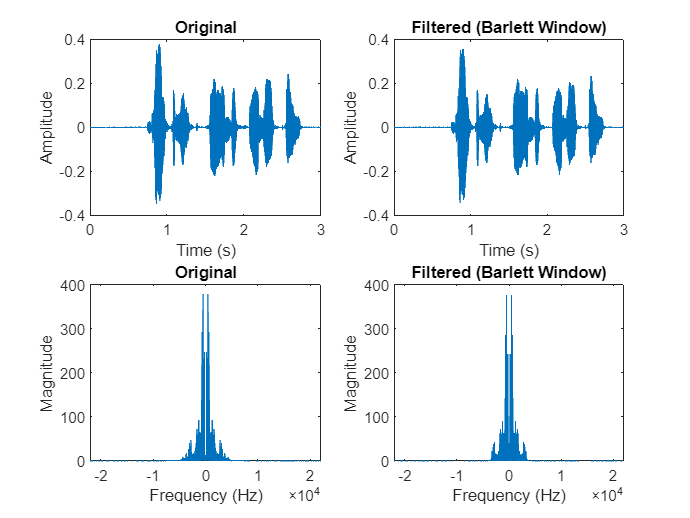

res = conv(x, h);
subplot(2,2,1);
t = (0:length(x)-1) / fs;
plot(t, x);
title('Original');
xlabel('Time (s)');
ylabel('Amplitude');
t = (0:length(res)-1) / Sampling_frequency; % Time vector

subplot(2,2,2);
plot(t, res);
title('Filtered (Barlett Window)');
xlabel('Time (s)');
ylabel('Amplitude');

n = length(x);  % Set n based on the length of the signal
y = fft(x, n);
m = abs(y);
f = (0:length(y)-1) * fs / length(y);
Y = fftshift(m);
fshift = (-n/2:n/2-1) * (fs/n);

% Filtered
nf = length(res);  % Set n based on the length of the signal
yf = fft(res, nf);
mf = abs(yf);
ff = (0:length(yf)-1) * Sampling_frequency / length(yf);
Yf = fftshift(mf);
fshiftf = (-nf/2:nf/2-1) * (Sampling_frequency/nf);

subplot(2,2,3);
plot(fshift, Y);
title('Original');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(2,2,4);
plot(fshiftf, Yf);
title('Filtered (Barlett Window)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');


% Ideal lowpass filter function


function hd = ideal_lp_filter(Wc, N)
    % Ideal lowpass filter function
    % Wc: Cutoff frequency
    % N: Filter order
    n = 0:N-1;
    hd = Wc / pi * sinc(Wc * (n - (N / 2)) / pi);
end

